## Question 2 - Part 2

#### Poisson Thinning


$$\lambda_{y}=4$$


Number of instances = $10^{5}$


$$p=0.8$$


rng(0);
lambdaY = 4;
p = 0.8;
n = 100000;

Creating random array of poisson distribution Y

Y = poissrnd(lambdaY, 1, n);

Calculating the thinned random Variable Z

Z = zeros(1, 26);
for i = 1:1:n
    r = binornd(Y(1, i), p); % getting a subset of Y(1, i) arrivals 
    if r < 26
        Z(1, r+1) = Z(1, r+1) + 1; % incrementing Z array for each instance
    end
end
Z = Z/n; % calculating the probability

Z

Z =     0.0408    0.1289    0.2099    0.2235    0.1765    0.1144    0.0606    0.0277    0.0120    0.0038    0.0013    0.0004    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0


Theoretically, $P(Z=k) = e^{-\lambda p}\frac{(\lambda p)^{k}}{k!}$

Now, plotting theoretical as well as experimental values,

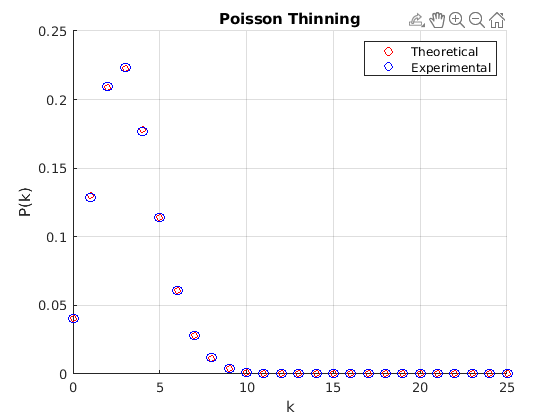

hold on;
for i=0:1:25
    scatter(i, pois(p*lambdaY, i), 20, 'r'); % theoretical
    scatter(i, Z(i+1), 50, 'b'); % experimental
end
hold off;

legend("Theoretical", "Experimental")
title("Poisson Thinning")
xlabel("k")
ylabel("P(k)")
grid on

Function returns , $e^{-\lambda}\frac{\lambda^{k}}{k!}$

function ret = pois(lambda, k)
    ret = exp(-lambda)*power(lambda, k)/factorial(k);
end